# SELEX7620 Lab 3

Name:  Taewoo Kim, A01284763, and set T

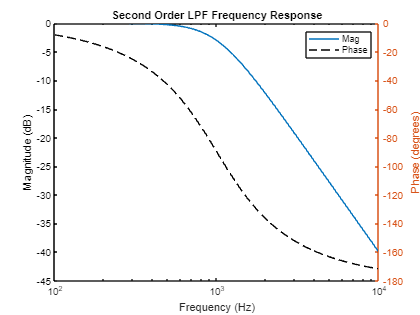

fc=1000;        %cutoff frequency in Hz
wc=2*pi*fc;     %cutoff frequency in rad/s
zeta = 1/sqrt(2);
%modify the code below to create the transfer function
%store transfer function in variable name H1 and H2
b = 1*wc^2;
a = [1 2*zeta*wc wc^2];
H = tf(b,a);  

%plot the frequency response
freq = logspace(2,4,50);
[mag, phase] = bode(H,2*pi*freq);
mag_dB = 20*log10(abs(mag(:,:)));
figure(1)
clf
semilogx(freq,mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Second Order LPF Frequency Response')
hold on
yyaxis right
semilogx(freq,phase(:,:),'k--')
ylabel('Phase (degrees)')
legend('Mag','Phase')
hold off

## Calculate Component Values for Tow Thomas Filter

## 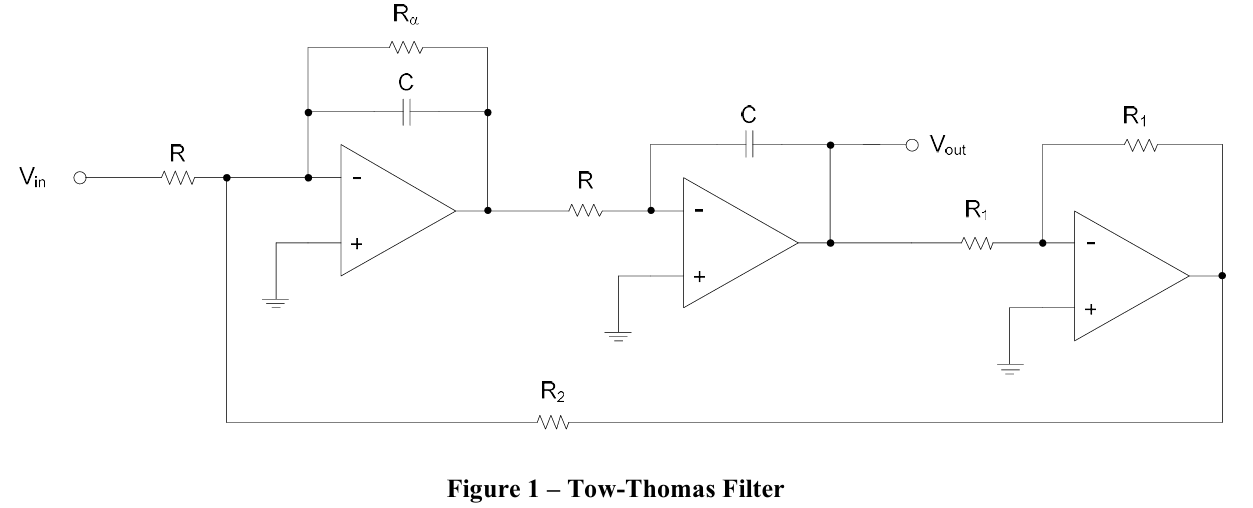

%Show your work for the steps below by inserting some documentation above or below this code block

%Set C
C = 0.1*10^-6

C = 1.0000e-07


%Calculate the values for R1 and R2
%R1 = ((C1/wc)+sqrt((C1/wc)^2 - 4*(C1*C2)* 1/(wc)^2))/(2*C1*C2)
%R2 = 1/(wc^2 * C1 * C2 * R1)
R = 1592

R = 1592

R2 = R

R2 = 1592

Ra = 1125

Ra = 1125

R1 = 47*10^3

R1 = 47000

Steps to calculate the values for Tow Thomas Filter:

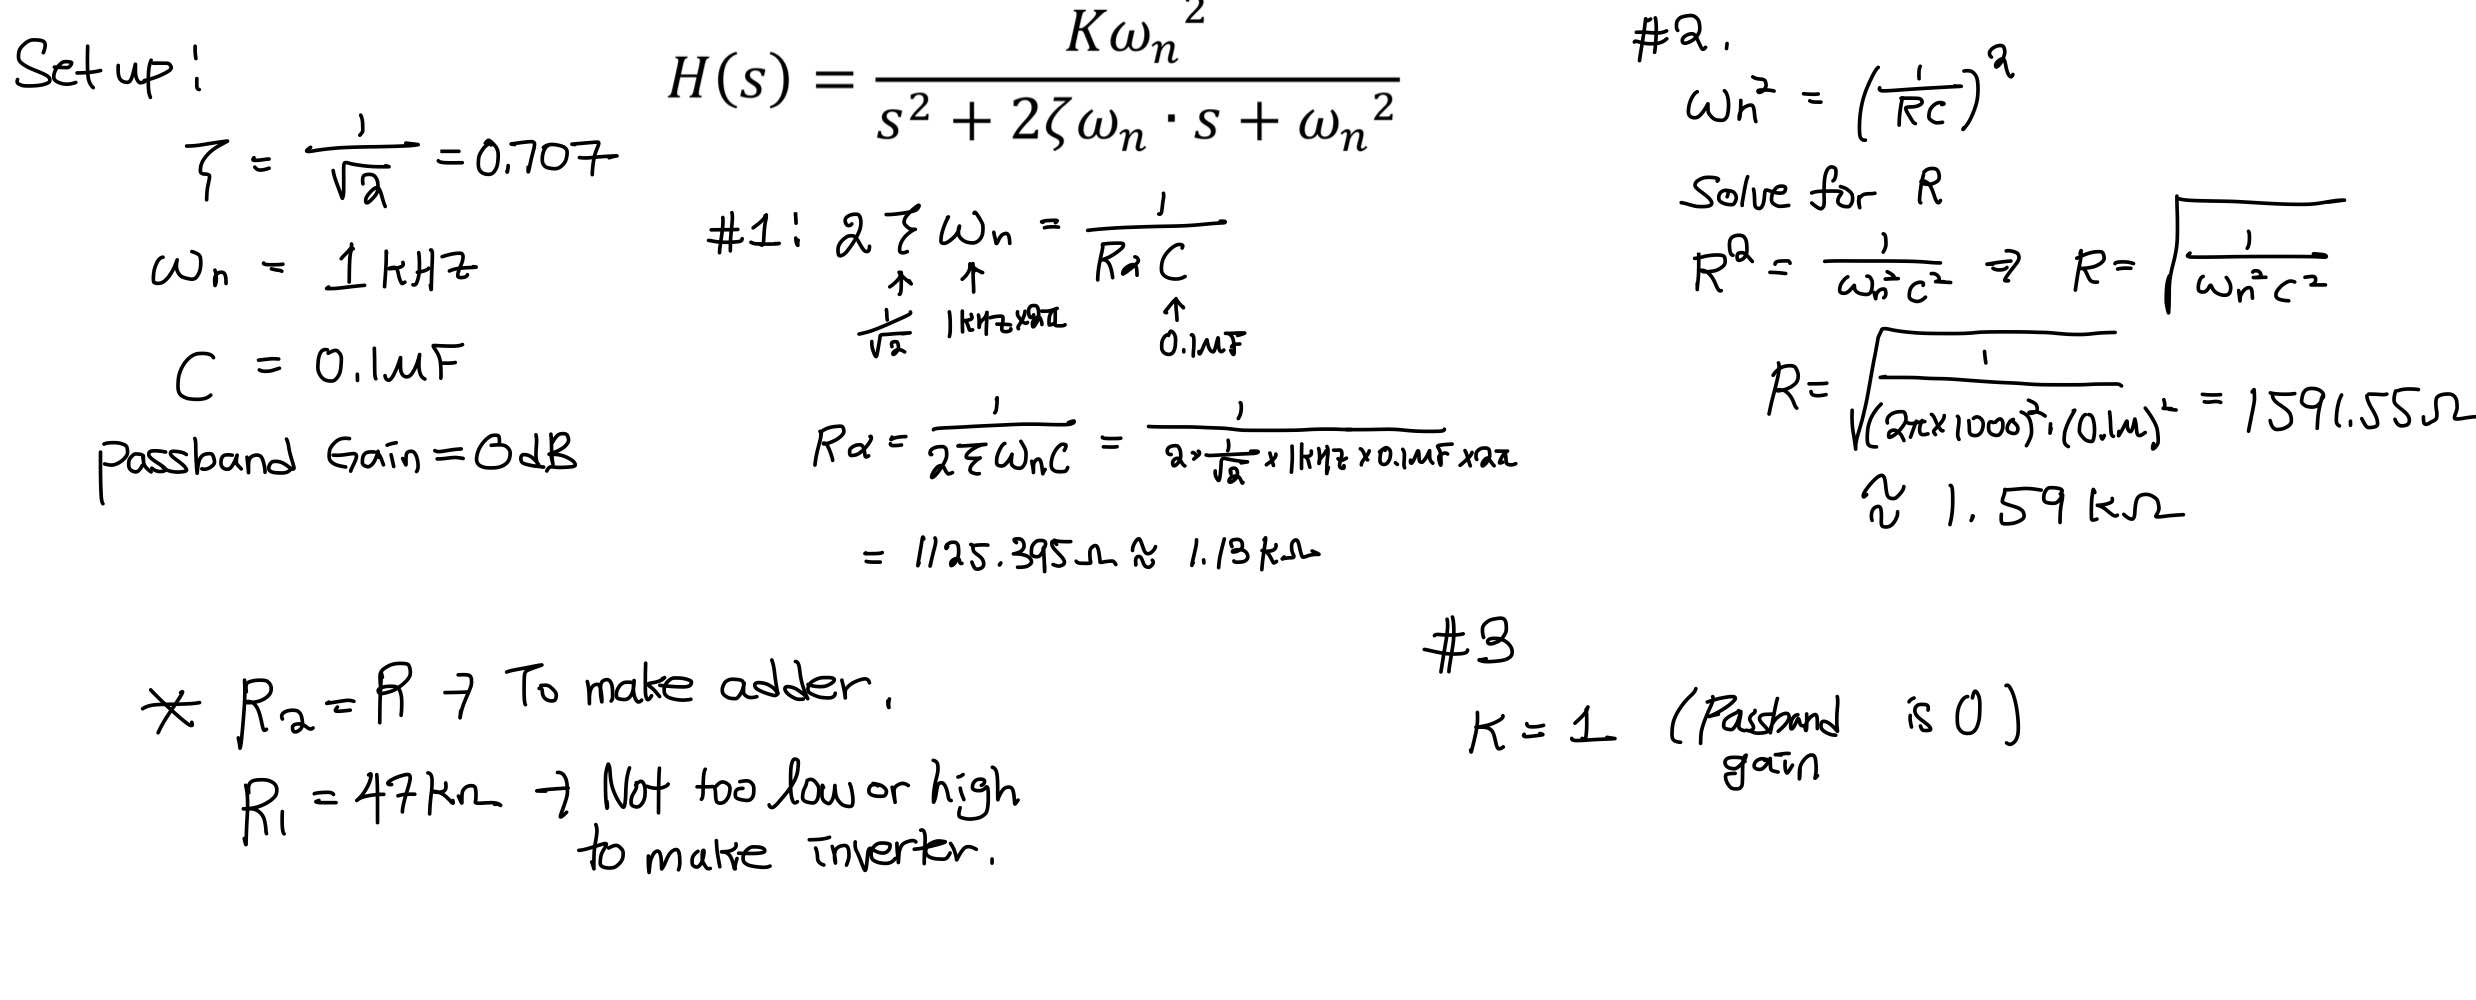

## LTSPICE Schematic

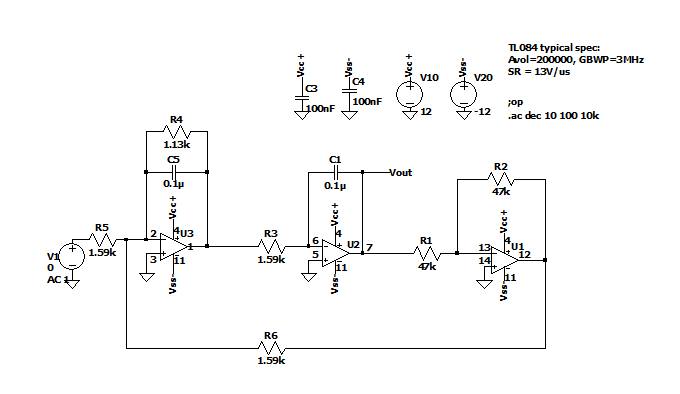

## LTSPICE Simulation Results

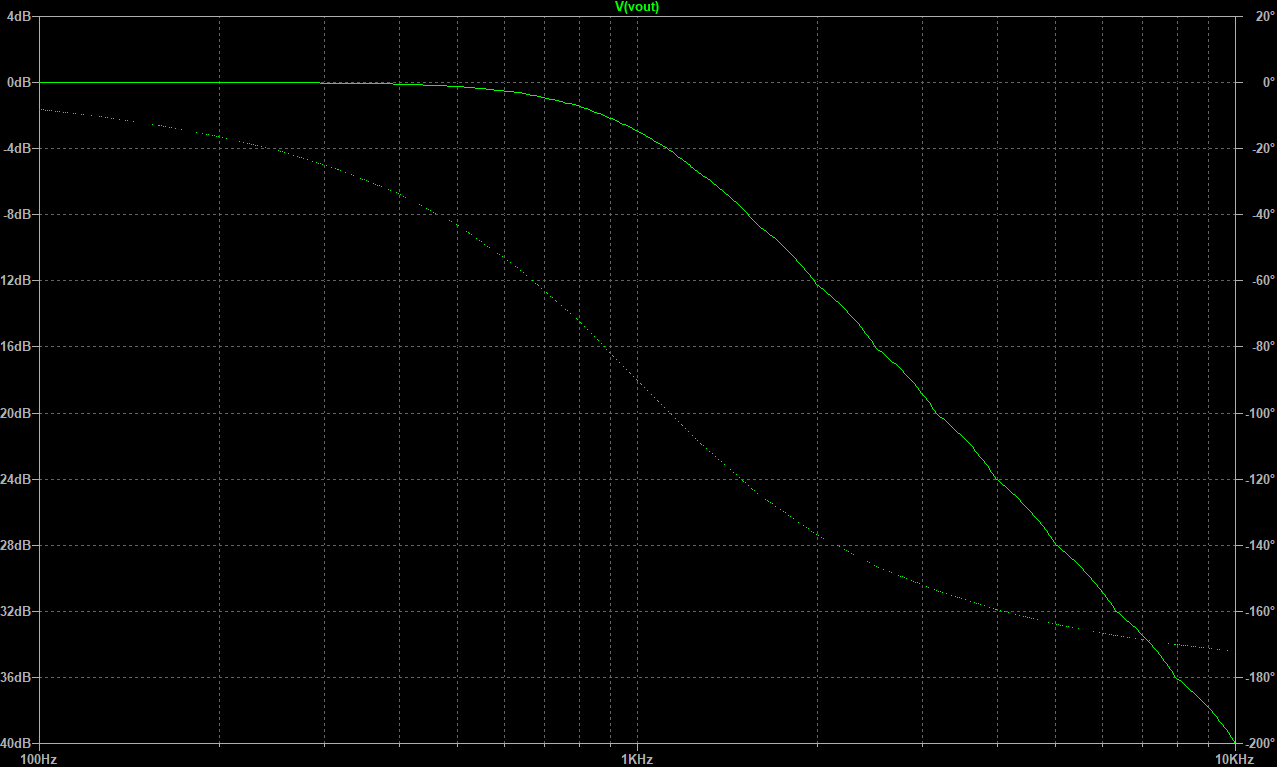

- Matlab plot and my ltspice simulation results match.

## **measurements:**

**Screenshot from AD2:**

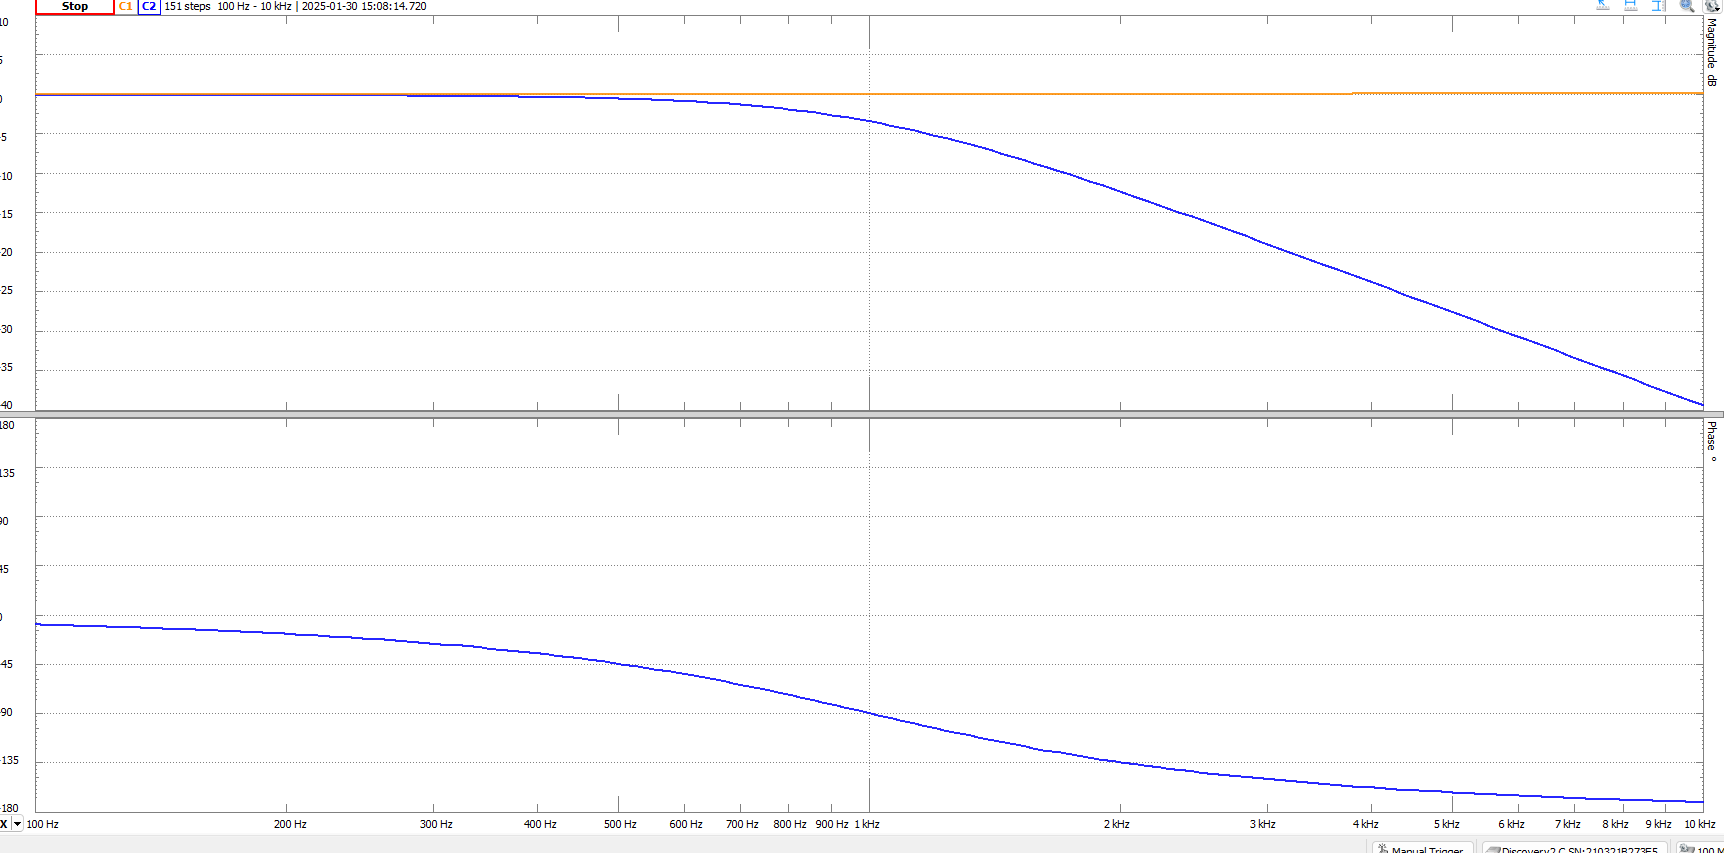

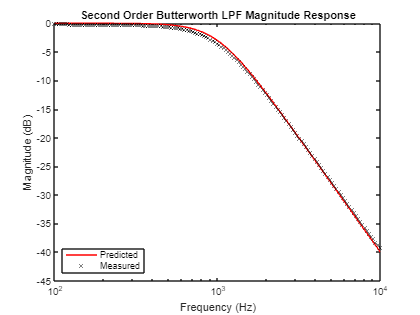

% Read table from the csv file
measured = readtable('butterworth.csv', 'VariableNamingRule', 'preserve');
% 
% % Extract all the values
meas_freq = measured.("Frequency (Hz)");
meas_mag_dB = measured.("Channel 2 Magnitude (dB)");
meas_phase = measured.("Channel 2 Phase (deg)");

figure(2)
clf
semilogx(freq,mag_dB,'r-',meas_freq,meas_mag_dB,'kx')
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Second Order Butterworth LPF Magnitude Response')
legend('Predicted', 'Measured', 'Location', 'southwest');

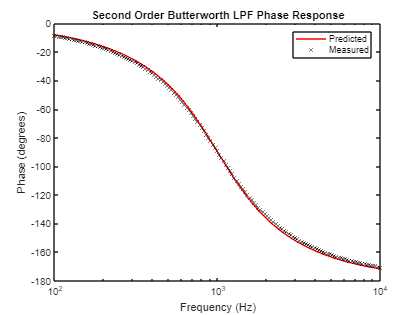


figure(3)
clf
semilogx(freq,phase(:,:),'r-',meas_freq,meas_phase,'kx')
xlabel('Frequency (Hz)')
ylabel('Phase (degrees)')
title('Second Order Butterworth LPF Phase Response')
legend('Predicted', 'Measured')

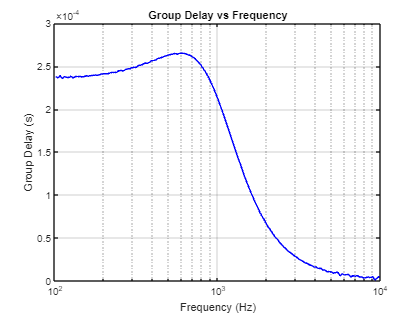



%%% Group delay %%%
%%% author: Taewoo Kim, ChatGPT %%%

% Convert phase from degrees to radians
meas_phase_rad = meas_phase * pi / 180;

% Compute angular frequency (omega)
omega = 2 * pi * meas_freq;

% Compute numerical derivative of phase with respect to omega
dphi_domega = diff(meas_phase_rad) ./ diff(omega);

% Compute group delay (negative derivative)
group_delay = -dphi_domega;

% Midpoints for plotting (since diff reduces length by 1)
freq_mid = (meas_freq(1:end-1) + meas_freq(2:end)) / 2;

% Plot Group Delay
figure;
semilogx(freq_mid, group_delay, 'b', 'LineWidth', 1.5);
grid on;
xlabel('Frequency (Hz)');
ylabel('Group Delay (s)');
title('Group Delay vs Frequency');

## **Bessel version of the Tow-Thomas Filter**

fc=1000;        %cutoff frequency in Hz
wc=2*pi*fc;     %cutoff frequency in rad/s
wn = wc*1.2574;  %Scaled inpute frequency for besself function

%modify the code below to create the transfer function
%store transfer function in variable name H1 and H2
[b, a] = besself(2, wn);
H = tf(b,a)

H =
 
           6.242e07
  ---------------------------
  s^2 + 1.368e04 s + 6.242e07
 
Continuous-time transfer function.
Model Properties


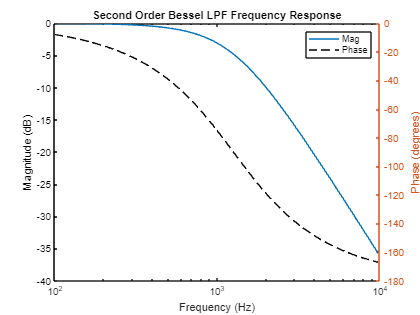


%plot the frequency response
freq = logspace(2,4,50);
[mag, phase] = bode(H,2*pi*freq);
mag_dB = 20*log10(abs(mag(:,:)));
figure(4)
clf
semilogx(freq,mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Second Order Bessel LPF Frequency Response')
hold on
yyaxis right
semilogx(freq,phase(:,:),'k--')
ylabel('Phase (degrees)')
legend('Mag','Phase')
hold off

Steps to calculate the values for Bessel Filter:

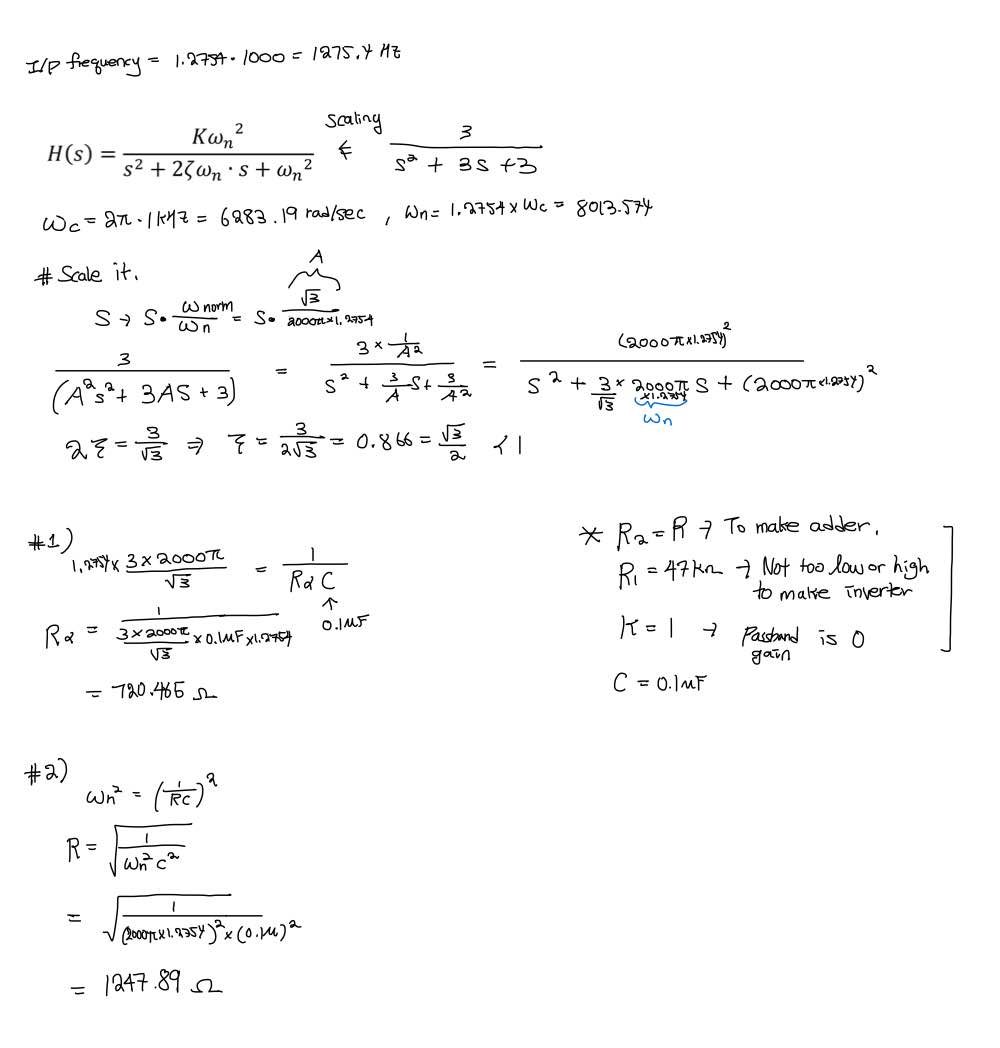

## LTSPICE Schematic

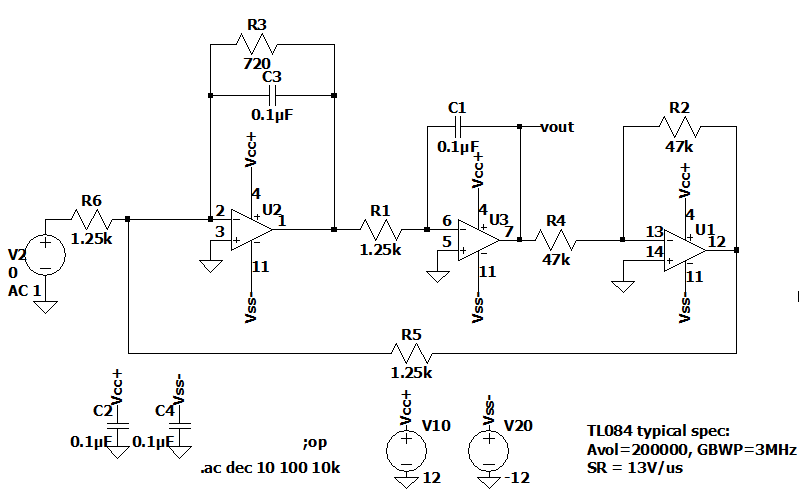

## LTSPICE Simulation Results

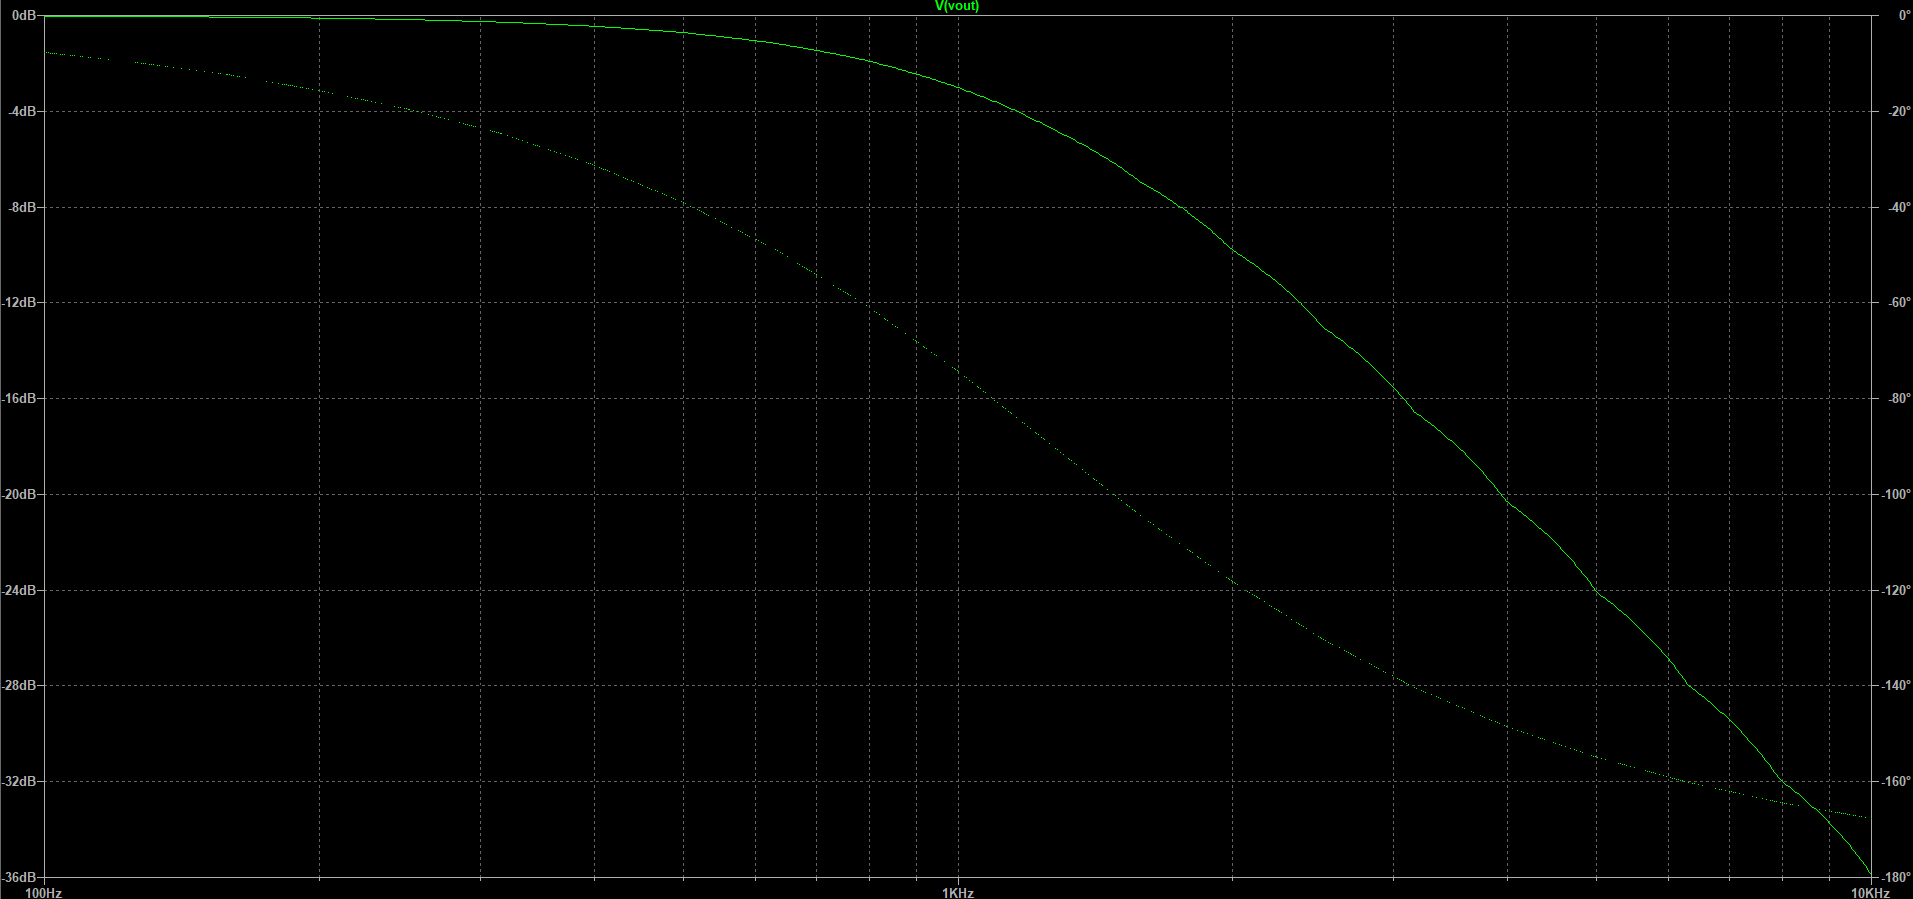

## **measurements:**

**Screenshot from AD2:**

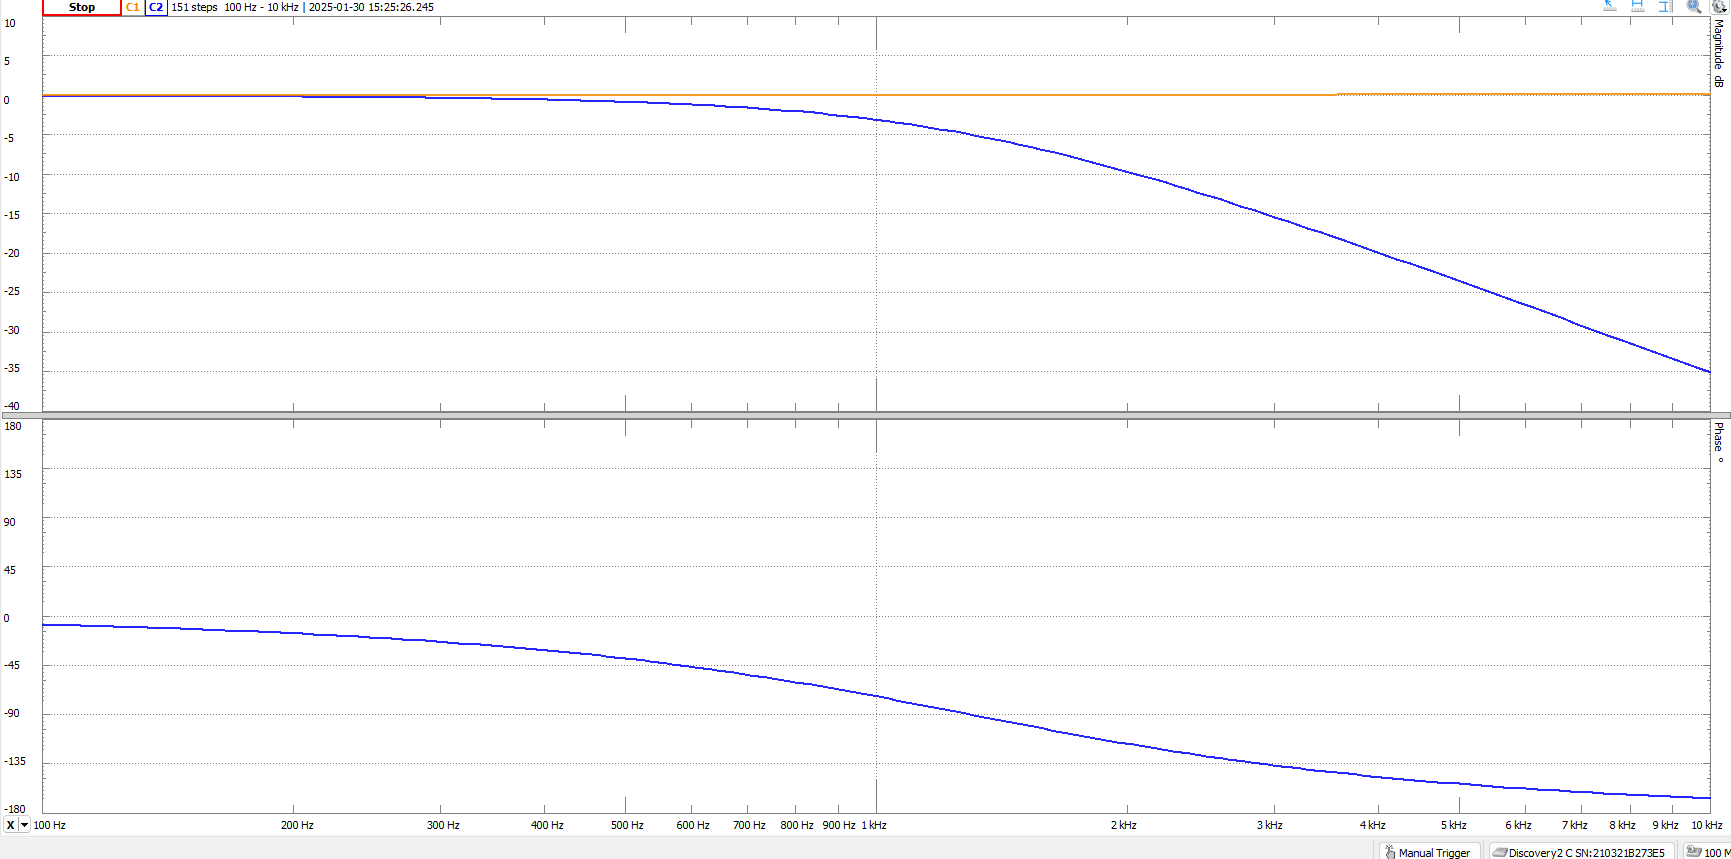

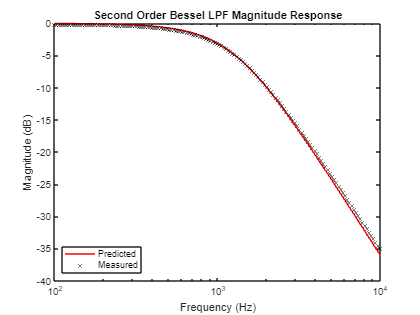

% Read table from the csv file
measured = readtable('bessel.csv', 'VariableNamingRule', 'preserve');
% 
% % Extract all the values
meas_freq = measured.("Frequency (Hz)");
meas_mag_dB = measured.("Channel 2 Magnitude (dB)");
meas_phase = measured.("Channel 2 Phase (deg)");

figure(2)
clf
semilogx(freq,mag_dB,'r-',meas_freq,meas_mag_dB,'kx')
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Second Order Bessel LPF Magnitude Response')
legend('Predicted', 'Measured', 'Location', 'southwest');

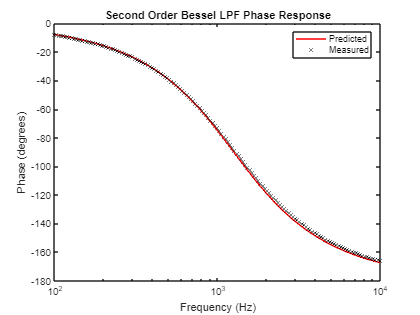


figure(3)
clf
semilogx(freq,phase(:,:),'r-',meas_freq,meas_phase,'kx')
xlabel('Frequency (Hz)')
ylabel('Phase (degrees)')
title('Second Order Bessel LPF Phase Response')
legend('Predicted', 'Measured')

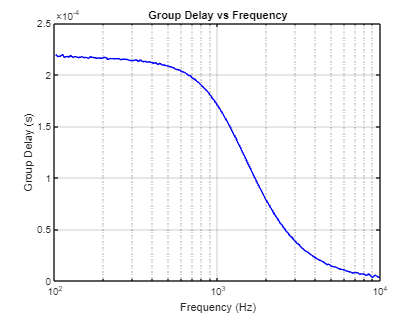



%%% Group delay %%%
%%% author: Taewoo Kim, ChatGPT %%%

% Convert phase from degrees to radians
meas_phase_rad = meas_phase * pi / 180;

% Compute angular frequency (omega)
omega = 2 * pi * meas_freq;

% Compute numerical derivative of phase with respect to omega
dphi_domega = diff(meas_phase_rad) ./ diff(omega);

% Compute group delay (negative derivative)
group_delay = -dphi_domega;

% Midpoints for plotting (since diff reduces length by 1)
freq_mid = (meas_freq(1:end-1) + meas_freq(2:end)) / 2;

% Plot Group Delay
figure;
semilogx(freq_mid, group_delay, 'b', 'LineWidth', 1.5);
grid on;
xlabel('Frequency (Hz)');
ylabel('Group Delay (s)');
title('Group Delay vs Frequency');